function plotBlondelPhasorDiagram(input_obj) 


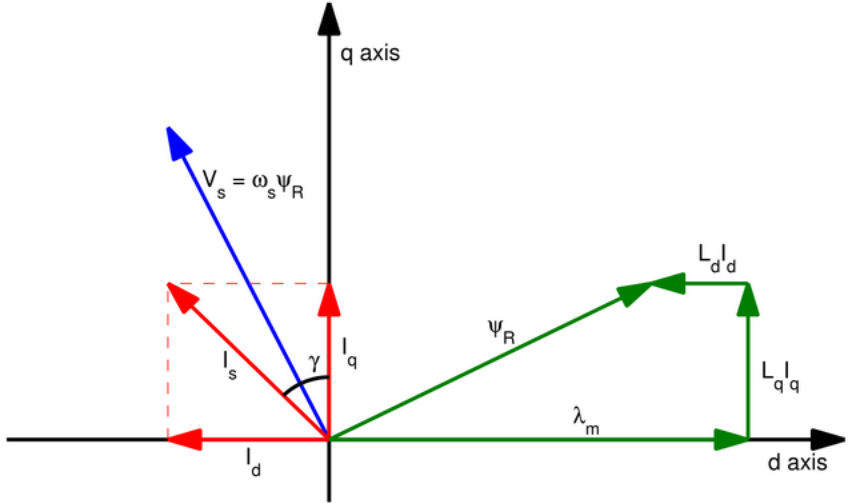

Venom=[114,140,0]./255;

## Angle


$$$\gamma$ (mcad, Speed)
$\phi$ (speed), $\theta$ $\varphi$= PF Angle  
$\delta$ (speed)= Load Angle
$\beta$ 
$\alpha$
$$


%%
xx=input_obj.RMSPhaseResistiveVoltage_D+input_obj.RMSPhaseReactiveVoltage_D
yy=input_obj.RmsBackEMFPhase+input_obj.RMSPhaseResistiveVoltage_Q+input_obj.RMSPhaseReactiveVoltage_Q;


% =rad2deg(atan(xx/yy)
% gamma (Phase Advance)
gamma.theta=rad2deg(acos(input_obj.RMSPhaseCurrent_Q/input_obj.RMSPhaseCurrent));
gamma.spandeg=[0,gamma.theta]

theta.theta=gamma.theta-rad2deg(atan(xx/yy));
theta.spandeg=[gamma.theta,gamma.theta-theta.theta];

% delta (Load Angle) ?
% \delta = gamma.theta-PFangle
Angdelta.theta=theta.theta+gamma.theta;
Angdelta.spandeg=[0,theta.spandeg(2)]



% theta = PFangle=[]; % PFangle, \theta V-I or \varphi
% theta.theta=rad2deg(atan(input_obj.RMSPhaseCurrent_D/input_obj.RMSPhaseCurrent_Q)-atan(xx/yy));


%% beta=[]; % \beta I or \phi
beta.theta= gamma.theta+rad2deg(pi/2)
% beta.theta=rad2deg(pi/2+atan(input_obj.RMSPhaseCurrent_D/input_obj.RMSPhaseCurrent_Q))
beta.spandeg=[0,beta.theta]

% flux linkage angle
alpha.theta=rad2deg(acot(input_obj.FluxLinkageLoad_D/input_obj.FluxLinkageLoad_Q)) 
alpha.spandeg=[0-90,alpha.theta-90];



## flux linkage (Green)

### dq Flux Linkage

figure(2)
quiver(0,0,1000*input_obj.FluxLinkageLoad_D,0,'off','g',LineWidth=2);
hold on
% text(alpha.x(50),alpha.y(50),'\alpha','FontSize',20)
hold on
quiver(1000*input_obj.FluxLinkageLoad_D,0,0,1000*input_obj.FluxLinkageLoad_Q,'off','g',LineWidth=2);
hold on
quiver(0,0,1000*input_obj.FluxLinkageLoad_D,1000*input_obj.FluxLinkageLoad_Q,'off','g',LineWidth=2);
hold on

%% Alpha
[alphaplot,alpha.x,alpha.y]=ang([0,0],input_obj.FluxLinkageLoad*30,deg2rad(alpha.spandeg),'b')


### InductanceXCurrent_Q, InductanceCurrentD

quiver(0,0,1000*input_obj.FluxLinkageQAxisCurrent_D,0,'off','Color',Venom);
hold on
quiver(1000*input_obj.FluxLinkageQAxisCurrent_D,0,0,1000*input_obj.InductanceQxCurrent_Q,'off','Color',Venom);
hold on
quiver(1000*input_obj.FluxLinkageQAxisCurrent_D,1000*input_obj.InductanceQxCurrent_Q,1000*input_obj.InductanceDxCurrent_D,0,'off','Color',Venom);
% Venom=[114,140,0]./255;

## Voltage

figure(3)
%% voltage
absReativeVoltage=sqrt(input_obj.RMSPhaseReactiveVoltage_D.^2+input_obj.RMSPhaseReactiveVoltage_Q.^2);

%% Voltage Drop(InductanceDrop)
Vy=input_obj.RmsBackEMFPhase+input_obj.RMSPhaseResistiveVoltage_Q
Vx=input_obj.RMSPhaseResistiveVoltage_D;
quiver(Vx,Vy,input_obj.RMSPhaseReactiveVoltage_D,0,'off','Color', [.5 0 .5]);
hold on

quiver(Vx+input_obj.RMSPhaseReactiveVoltage_D,Vy,0,input_obj.RMSPhaseReactiveVoltage_Q,'off','Color', [.5 0 .5]);
hold on
quiver(Vx,Vy,input_obj.RMSPhaseReactiveVoltage_D,input_obj.RMSPhaseReactiveVoltage_Q,'off','Color', [.5 0 .5])


% Voltage plot
%Plot BEMF
quiver(0,0,0,input_obj.RmsBackEMFPhase,'off','r',LineStyle='--');
text(0,input_obj.RmsBackEMFPhase*2/3,strcat(num2str(input_obj.RmsBackEMFPhase),'    ', 'E BEMF phase_{rms}[V]'))
hold on

%% Express Resitive RMSPhaseResistiveVoltage with  - need RmsBackEMFPhase RMSPhaseResistiveVoltage_D RMSPhaseResistiveVoltage_Q
quiver(0,input_obj.RmsBackEMFPhase,input_obj.RMSPhaseResistiveVoltage_D,input_obj.RMSPhaseResistiveVoltage_Q,'off','r');
text(input_obj.RMSPhaseResistiveVoltage_D,input_obj.RMSPhaseResistiveVoltage_Q+input_obj.RmsBackEMFPhase,strcat(num2str(input_obj.RMSPhaseResistiveVoltage),'    ', 'Phase D Voltage_R'))
hold on

%Plot Q drop
quiver(input_obj.RMSPhaseResistiveVoltage_D,input_obj.RmsBackEMFPhase+input_obj.RMSPhaseResistiveVoltage_Q,0,input_obj.RMSPhaseReactiveVoltage_Q,'off','r');
text((input_obj.RMSPhaseResistiveVoltage_D+0)/2,(input_obj.RmsBackEMFPhase+input_obj.RMSPhaseReactiveVoltage_Q/3*2),strcat(num2str(input_obj.RMSPhaseReactiveVoltage_Q),'    ', 'Phase VoltageQ_{Reactive}'))
hold on

%Plot D drop
quiver(input_obj.RMSPhaseResistiveVoltage_D,input_obj.RmsBackEMFPhase+input_obj.RMSPhaseResistiveVoltage_Q+input_obj.RMSPhaseReactiveVoltage_Q,input_obj.RMSPhaseReactiveVoltage_D,0,'off','r');
text((input_obj.RMSPhaseResistiveVoltage_D+input_obj.RMSPhaseReactiveVoltage_D)/3*2,(input_obj.RmsBackEMFPhase+input_obj.RMSPhaseReactiveVoltage_Q+10),strcat(num2str(input_obj.RMSPhaseReactiveVoltage_D),'    ', 'Phase VoltageD_{Reactive}'))
hold on



## Current

dqplane=figure(4)
quiver(0,0,0,input_obj.RMSPhaseCurrent_Q,'off','b',LineWidth=3);
text(0,2/3*(input_obj.RMSPhaseCurrent_Q),strcat(num2str(input_obj.RMSPhaseCurrent_Q),'    ','I_q_{rms}[A]'))
hold on

quiver(0,input_obj.RMSPhaseCurrent_Q,input_obj.RMSPhaseCurrent_D,0,'off','b',LineWidth=3);
text(2/3*(input_obj.RMSPhaseCurrent_D),1.05*input_obj.RMSPhaseCurrent_Q,strcat(num2str(input_obj.RMSPhaseCurrent_D),'    ', 'I_d_{rms}[A]'),"FontSize",20)
hold on 

quiver(0,0,input_obj.RMSPhaseCurrent_D,input_obj.RMSPhaseCurrent_Q,'off','b',LineWidth=3);
sqrt(input_obj.RMSPhaseCurrent_D.^2+input_obj.RMSPhaseCurrent_Q.^2)==input_obj.RMSPhaseCurrent
text(2/3*(input_obj.RMSPhaseCurrent_D),2/3*(input_obj.RMSPhaseCurrent_Q)-10,strcat(num2str(input_obj.RMSPhaseCurrent),'    ','I_{rms}[A]'))

%% gamma plot 
[gammaplot,gamma.x,gamma.y]=ang([0,0],yy*10,deg2rad(gamma.spandeg),'r')
text(gamma.x(50), gamma.y(50), ['$\gamma=$', num2str(gamma.theta), '$^\circ$'], ...
     'FontSize', 20, 'Interpreter', 'latex');

% % beta plot

% [betaplot,beta.x,beta.y]=ang([0,0],yy*10,deg2rad(beta.spandeg),'r')
% text(beta.x(50),beta.y(50),'\beta','FontSize',20)
% formatter_sci_phasor_diagram

%%

%%Plot Voltage_s
% quiver(0,0,xx,yy,'off','r');
%theta plot
% [thetaplot,theta.x,theta.y]=ang([0,0],yy*10,deg2rad(theta.spandeg),'b')
% text(theta.x(50),theta.y(50),'\theta','FontSize',20)

%delta plot
% [deltaplot,Angdelta.x,Angdelta.y]=ang([0,0],sqrt(xx.^2+yy.^2),deg2rad(Angdelta.spandeg),'b')
% text(Angdelta.x(50),Angdelta.y(50),'\delta','FontSize',20)


% text(2/3*xx,2/3*yy,strcat(num2str(input_obj.PhasorRMSPhaseVoltage),'Phase Terminal Voltage_{rms}[V]'))
% input_obj.PhasorRMSPhaseVoltage == sqrt(xx.^2+yy.^2)


% 
% 
% alpha.theta=rad2deg(acot(input_obj.FluxLinkageLoad_D/input_obj.FluxLinkageLoad_Q)) % flux linkage angle
% alpha.spandeg=[0-90,alpha.theta-90];
% 
% % quiver axis
% % !!!!!! important 'off' in quiver is autoscale must be included
% 
% 
% quiver(0,0,1000,0,'off','k',LineWidth=1,MaxHeadSize=0.05)
% hold on
% quiver(0,0,0,1000,'off','k',LineWidth=1,MaxHeadSize=0.05)
% hold on
% quiver(0,0,-1000,0,'off','k',LineWidth=1,MaxHeadSize=0.05)
% data_type=2 % 1 : pk plot 2: rms plot

figure(1)
blondelPhasorDiagram(input_obj) 
end
